- Llegim la imatge RGB i apliquem un filtre medfilt2 [1 4] per treure soroll:

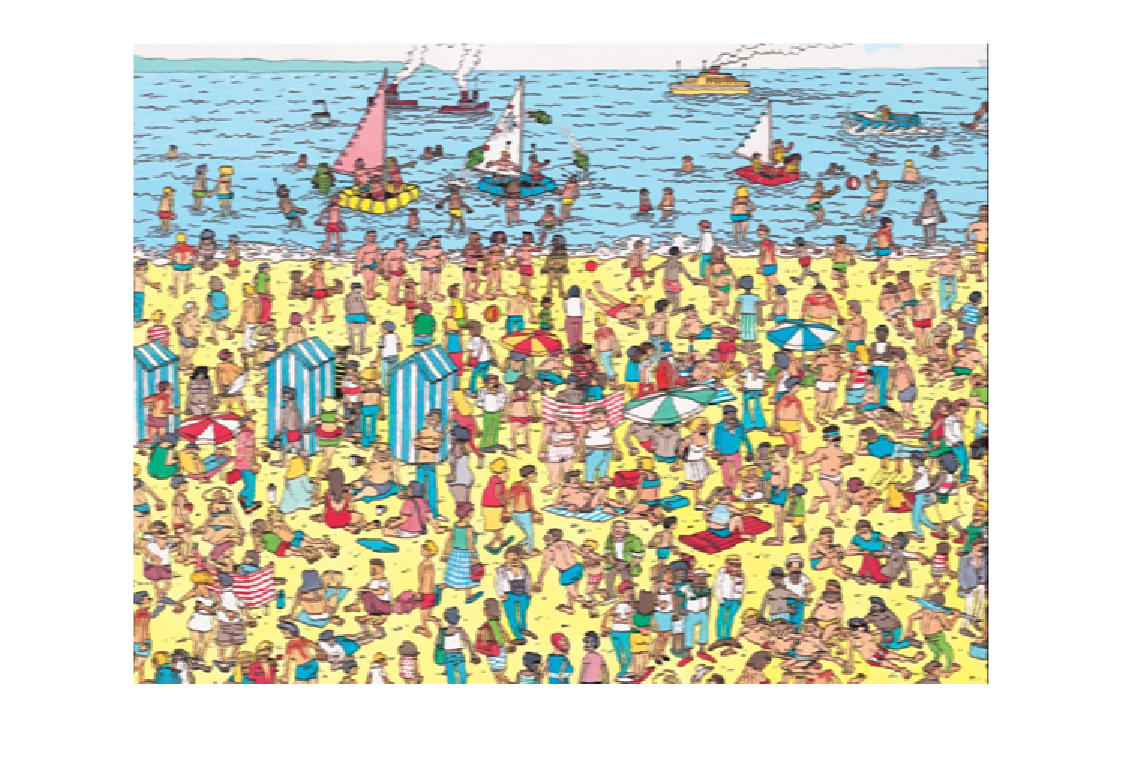

I = imread("Wally.png");
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);
R = medfilt2(R,[1,4]);
G = medfilt2(G,[1,4]);
B = medfilt2(B,[1,4]);
I = cat(3,R,G,B);
imshow(I);

Podem observar que ens queda lmatge original una mica difuminada, això es el que volem.

2. Convertim a un espai de color HSV

HSV = rgb2hsv(I);

3. Detectem el color groc per HUE = 50º +- tolerancia

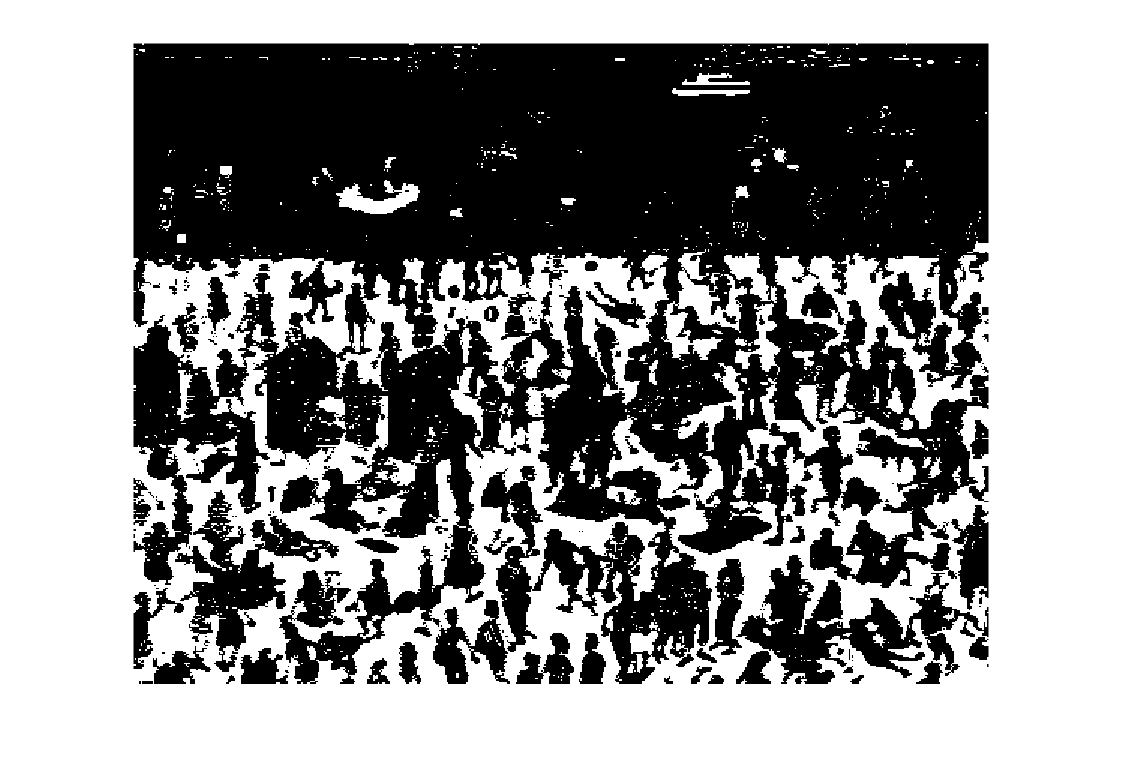

colorG = 50/360;
tol = 0.05;
GROC = HSV(:,:,1) > (colorG - tol) & HSV(:,:,1) < (colorG + tol);
imshow(GROC);

Podem observar la imatge on els pixels blancs corresponen a les seccións grogues de la imatge. He escollit una tolerancia de 0.05 perquè dona bons resultats.

4. Detectem el color negre que correspon als pixels amb els tres components RGB baixos o en cas de HSV correspon a un Value baix

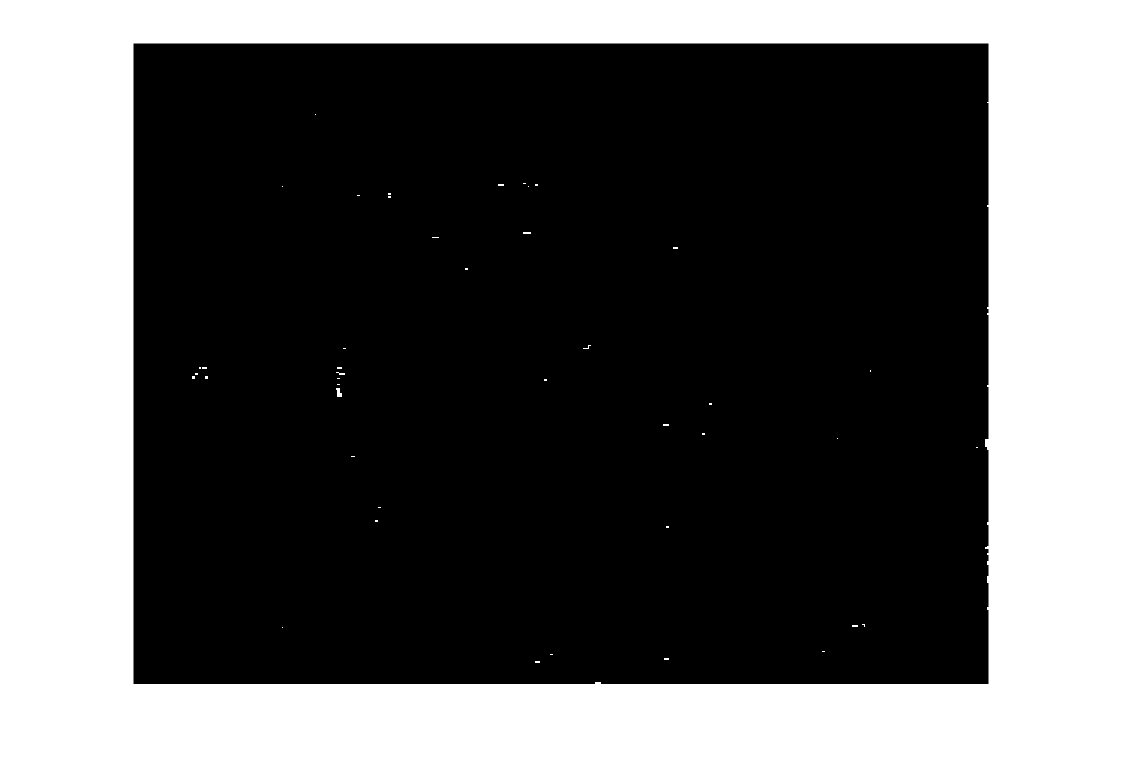


NEGRE = HSV(:,:,3) < 0.15;
imshow(NEGRE);

Podem observar la imatge on els pixels blancs corresponen a les seccións negres de la imatge. He escollit els pixels amb Value < 0.15 perquè dona bons resultats.

5. Filtrar per detectar patrons de línies **grogues** horitzontals amb SE7 = strel('line',7,90);

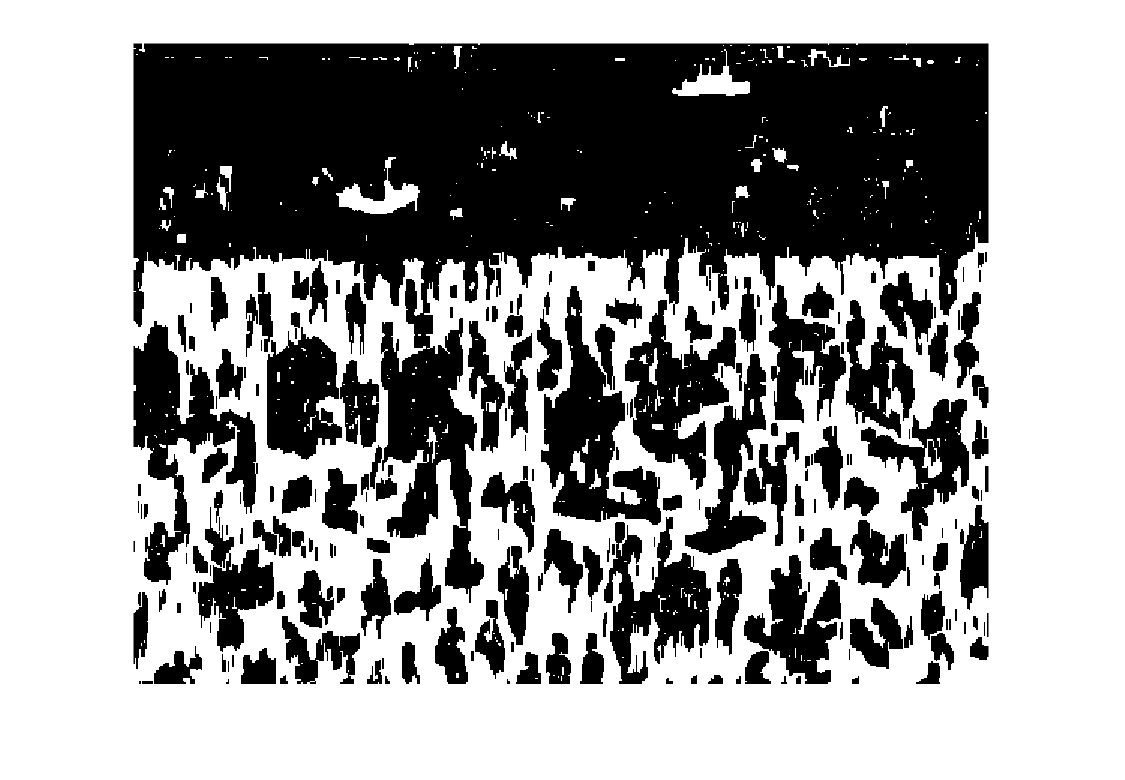

SE7 = strel('line',7,90);
GROCT = imclose(GROC,SE7);
imshow(GROCT);

Fem un close del color groc per tal d'ajuntar linies properes i elminar petites regions aïllades.

6. Filtrar per detectar patrons de línies **negres** horitzontals amb SE7 = strel('line',7,90);

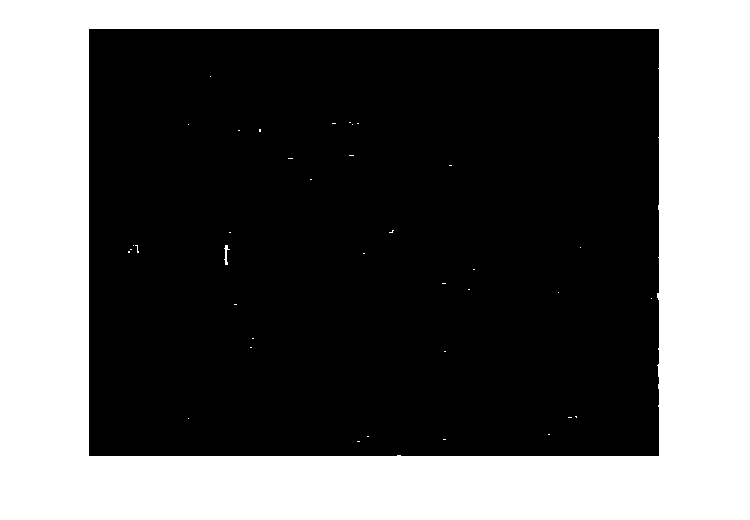

NEGRET = imclose(NEGRE,SE7);
imshow(NEGRET);

Fem el mateix que pel color groc pero pel negre, fem un close per ajuntar línies properes i eliminar les petites línies aïllades.

7. Unim els dos resultats amb una **and** lògica.

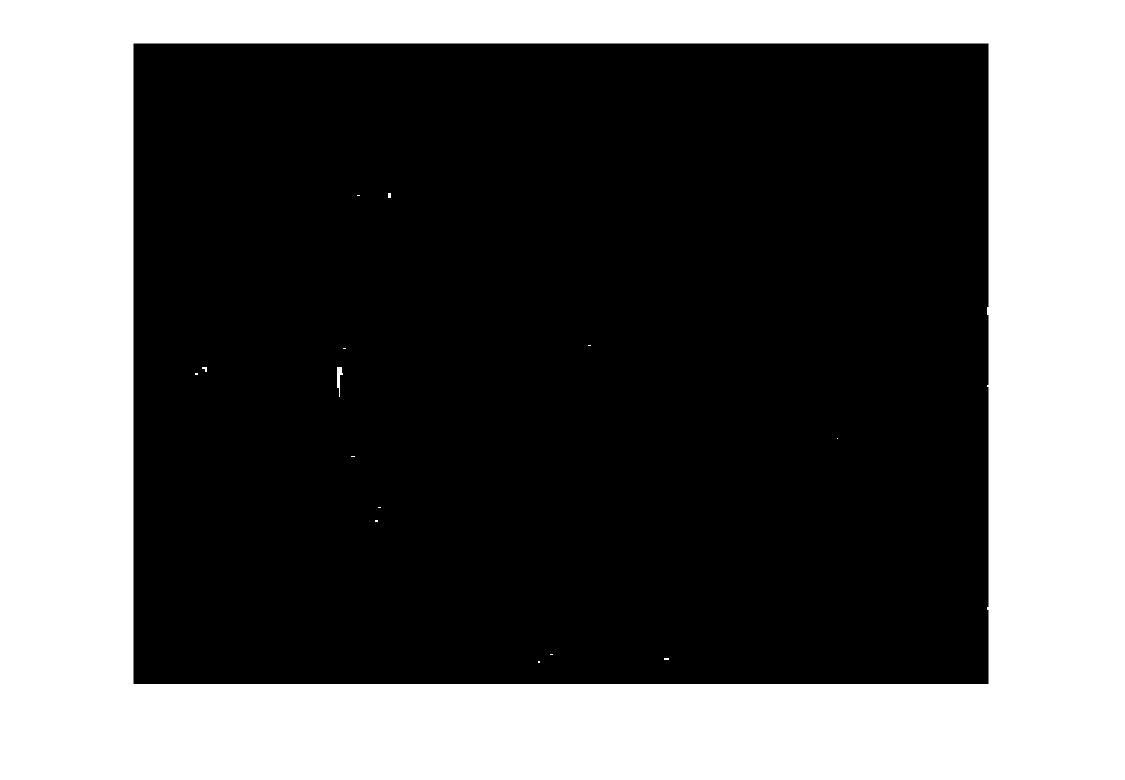

RES = GROCT&NEGRET;
imshow(RES);

Amb la **and** lògica del color negre amb el color groc ens queda una matriu resultant amb pixels blancs a les seccions on hi ha color negre i groc de imatge original.

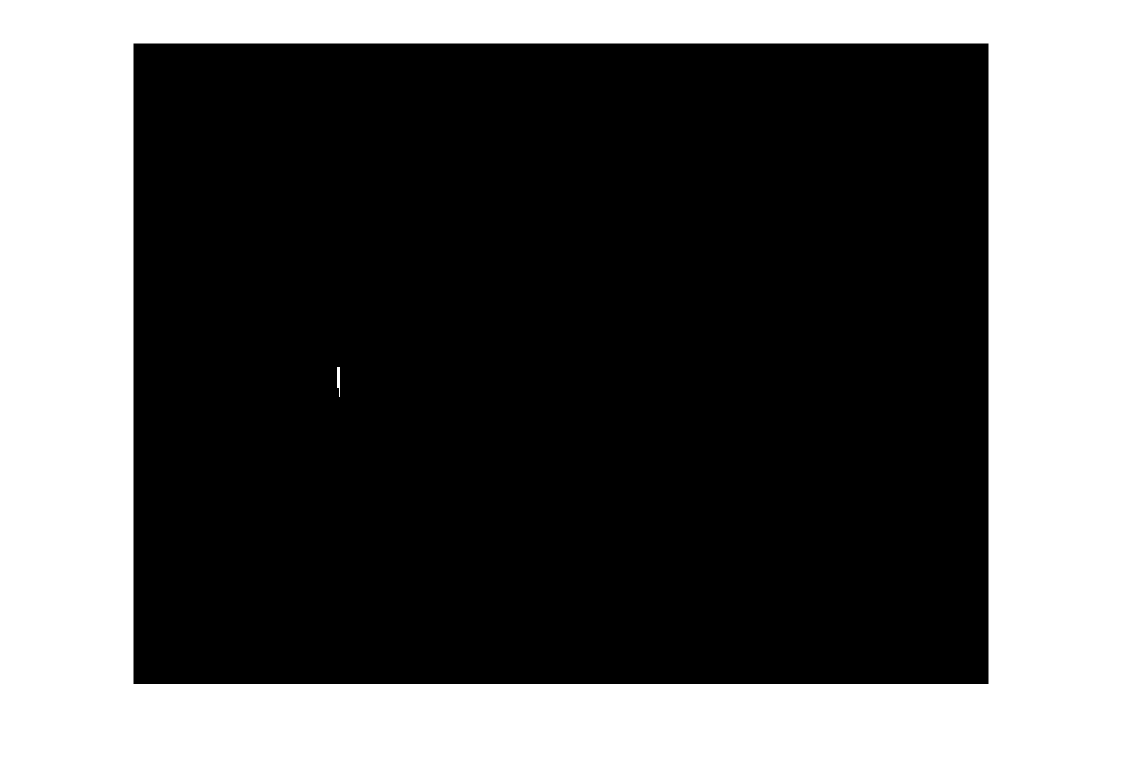

SE = strel('line',7,90);
RESO = imopen(RES,SE);
imshow(RESO);

Abans de dilatar per veure clarament la posició de l'Odlaw, hem de treure tots les elements blancs que no son l'Odlaw, podem veure que totes les seccions blanques excepte la de l'Odlaw son petits elements blancs (en canvi l'Odlaw es una línea vertical de tamany notable). Per tant podem fer un open amb un element estructurant en forma de linia vertical, això ens elimina petits elements blancs aïllats que es justament el que volem.

8. Dilatem els píxels "supervivents"

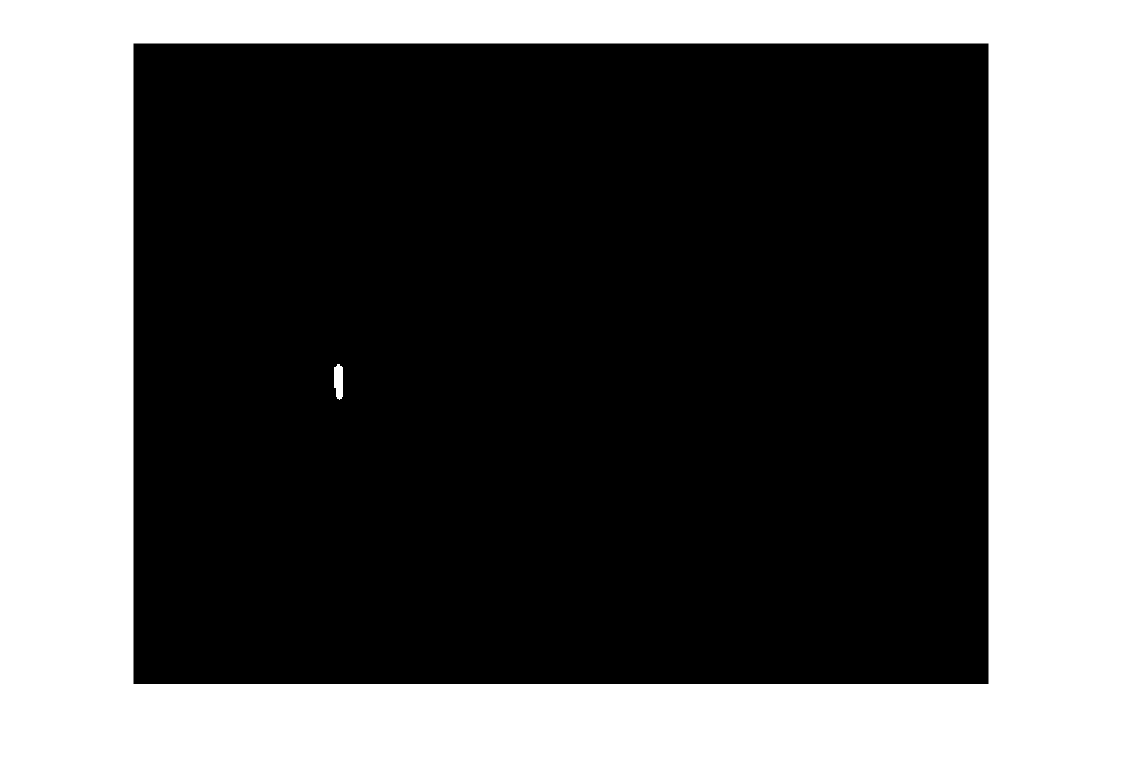

SE2 = strel('disk',2);
RESD = imdilate(RESO,SE2);
imshow(RESD);

Al dilatar la única secció blanca, fem més gran la secció on hem detectat que es troba l'Odlaw

9. Realitzem una composició de la imatge original en gris i el resultat en vermell superposat.

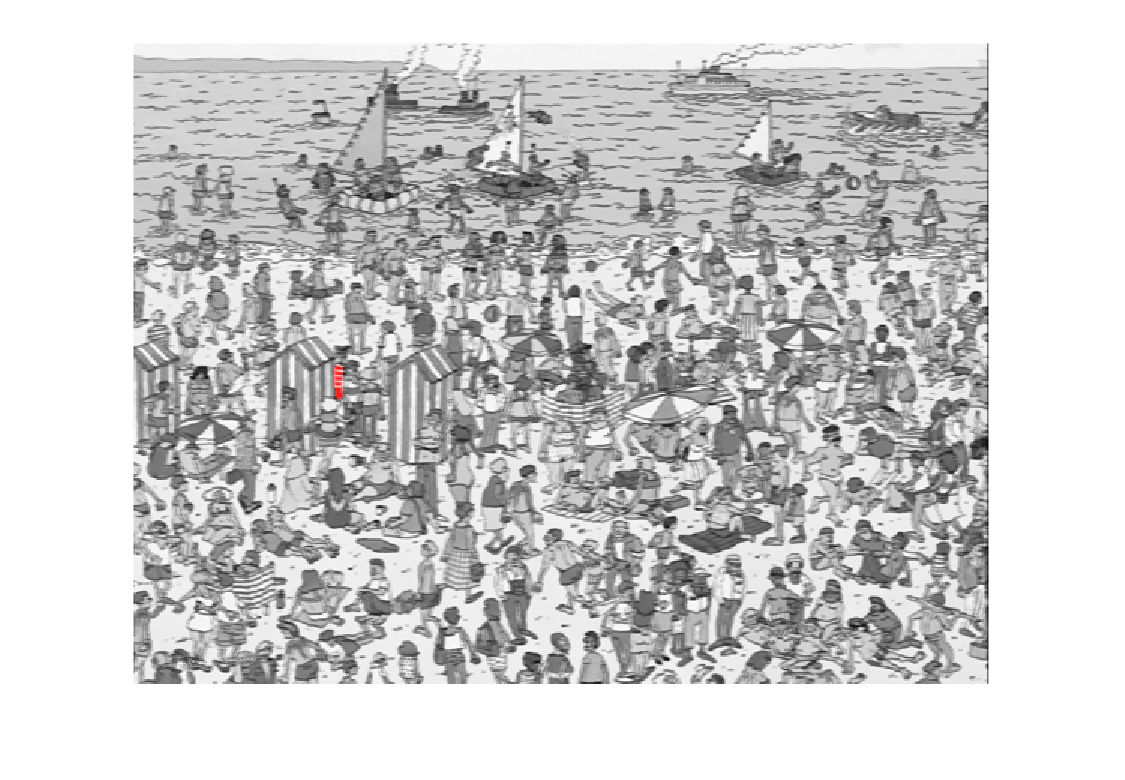


ImgOriginal = rgb2gray(I);
ImgFinal = cat(3, ImgOriginal, ImgOriginal, ImgOriginal);
ImgFinal(:,:,1) = ImgFinal(:,:,1) + uint8(RESD*255);
imshow(ImgFinal);

La imatge resultat correspón a la imatge original passada a escala de grisos afegintli a la component vermella (R) el valor de RESD (on la secció blanca correspon al lloc on es troba l'Odlaw) passada de [0 1] a [0 255]. Podem veure a a imatge final que la secció vermella es just a sobre d'on es l'Odlaw per tant, la detecció és correcta.